# Computer Vision Lab 3

# Feature detection and matching

**Authors**: Emer Rodriguez Formisano and Jorge Alexander  

**Date**: 24/10/2017

## 1. Introduction

run('~/vlfeat-0.9.20/toolbox/vl_setup');
vl_version

0.9.20


## 2. Feature detection

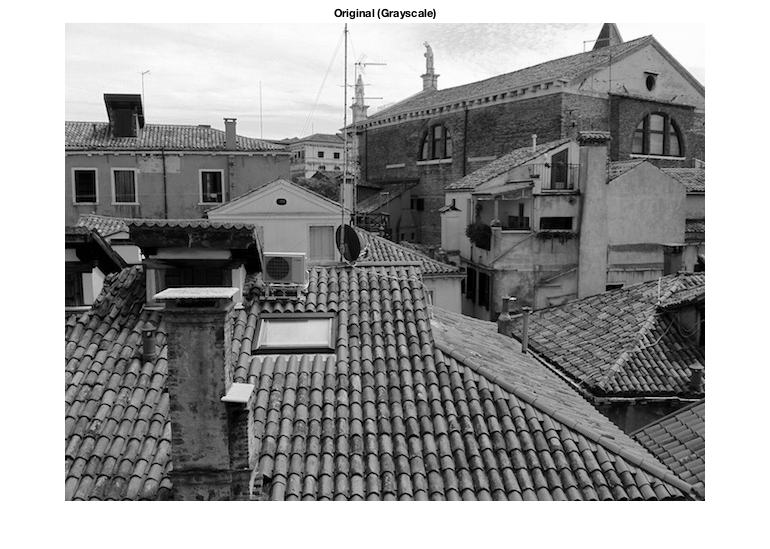

I = vl_impattern('roofs1');
I = single(rgb2gray(I));
imshow(I), title('Original (Grayscale)');

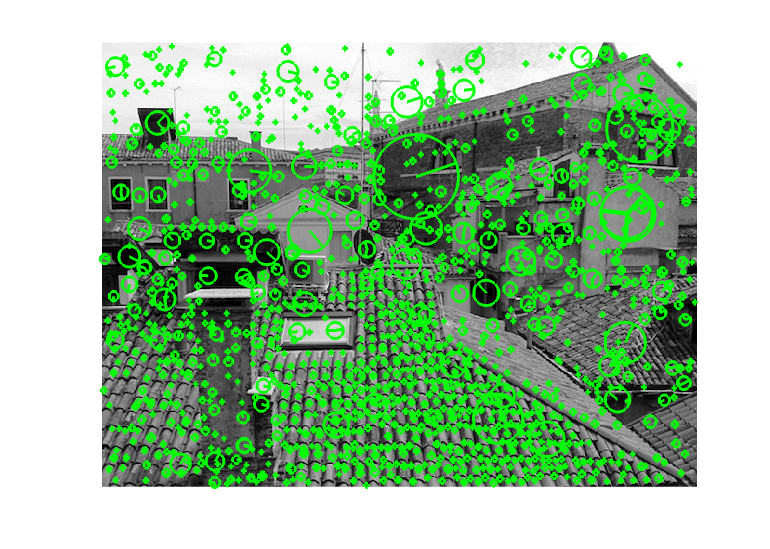

[f, d] = vl_sift(I);
show_keypoints(I, f);

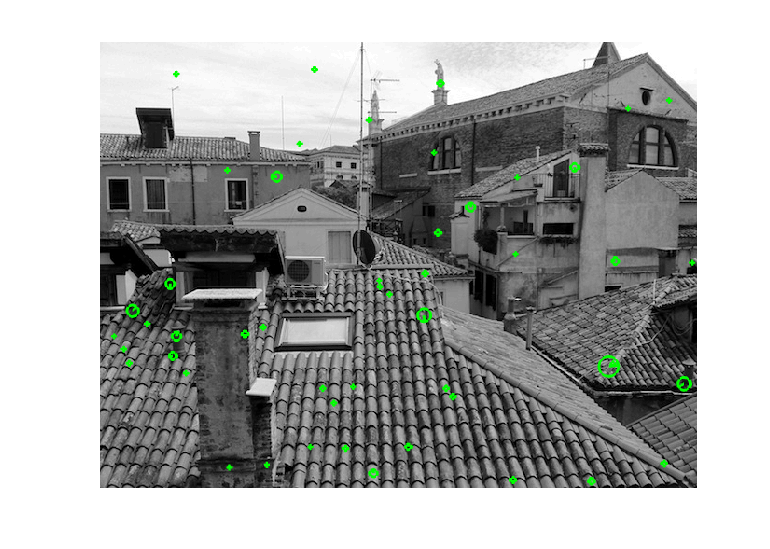

show_keypoints(I,random_selection(f,50))

**Question 1**: Take at your own choice several keypoints that have been detected at different scales. Using the theory given in the lectures, comment on the reasons of why do you think that a keypoint has been detected at that position and at that particular scale. You may repeat the experiment with another image (such as 'river1') to understand what a significant keypoints is.

First let's consider the scale of the keypoints:

scale_std = std(f(3,:));
scale_mean = mean(f(3,:));

Let us see the keypoints that are three std deviations

above the mean

idx = f(3,:) > (scale_mean + 3*scale_std);
sub_f = f(:, idx);
show_keypoints(I, sub_f);

An interesting keypooint to note are three overlapping ones to the right of the image. Let's isolate them:

size_I = size(I);
width_I = size_I(1);
height_I = size_I(2);

The right 5% of the image is selected:

idx = sub_f(1,:) > (width_I * 0.95);
sub_f = sub_f(:, idx);

The vertical 20-50% if the image is selected:

idx = sub_f(2,:) > (height_I * 0.2);
sub_f = sub_f(:, idx);
idx = sub_f(2,:) < (height_I * 0.5);
sub_f = sub_f(:, idx);

The keypoints are now isolated

show_keypoints(I, sub_f);

Three key points of equal scale, but different orientations, are observed. The reason for the detection of these keypoints and this scale, can be explained by the part of the image that they are on. They are on a smooth wall which at a smaller scale would not show keypoints, as the intensity is similar across the area of the wall. However, at the scale of the selected keypoints, there is a strong gradient change created at edges of the smooth wall. These gradient changes being in different directions cause the different orientations of the keypoints.

**Question 2:** Which is the effect when using the peak threshold=0.01 on the 'roofs1' image? Comment the differences with respect to the previous result (default value of the peak threshold=0).

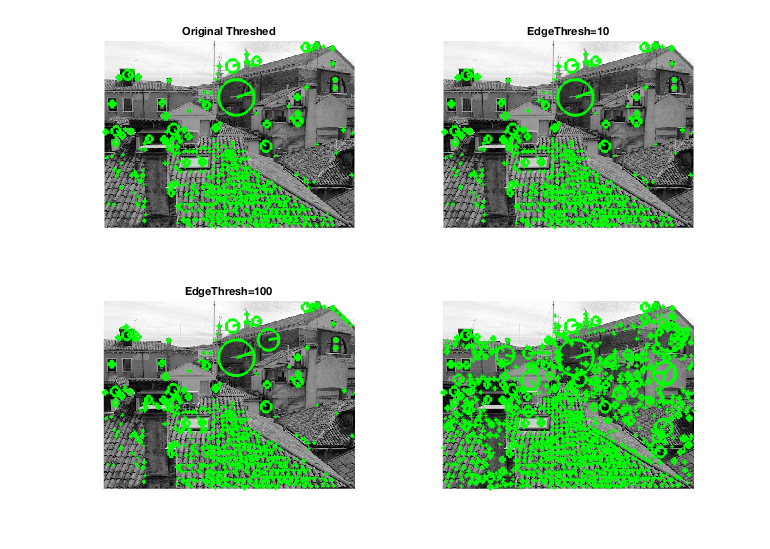

thresh = 0.01;
[f_threshed, ~] = vl_sift(I,'PeakThresh', thresh);
show_keypoints(I,f_threshed);

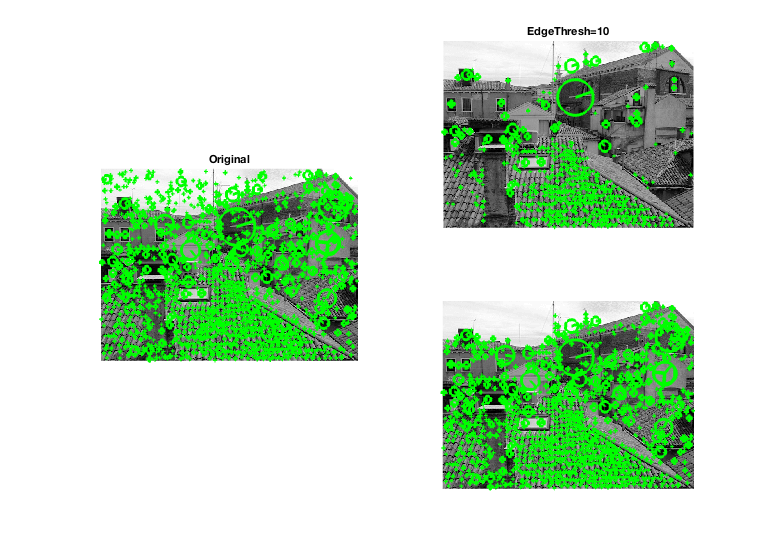

subplot(1,2,1); show_keypoints(I,f); title('Original');

subplot(1,2,2); show_keypoints(I,f_threshed); title('Threshed');

It is observed that in the threshed image, less keypoints are found.

keypoint_diff = size(f) - size(f_threshed); % 190 less

This is because keypoints were left out of the threshed image that failed to pass the difference of Gaussian test:

|D(xˆ)| > γ

It checks that the absolute value of the difference of gaussian is above the threshold, and hence helps reduce the sensitivity to noise. 

For example, in the threshed roof image, there are significantly less keypoints located in the sky. This is because the sky has several small dots of gradient difference, which is detected in the unthreshed image. By applying the threshold it is correctly filtered out. The overall gradient difference over the sky area stays approximately the same, and is therefore not a good area for keypoints.

**Question 3:** Try to slowly increase or decrease the threshold. Comment why the number of detected keypoints decreases when the threshold is increased. Is this the expected behavior according to the way the threshold is de defined?

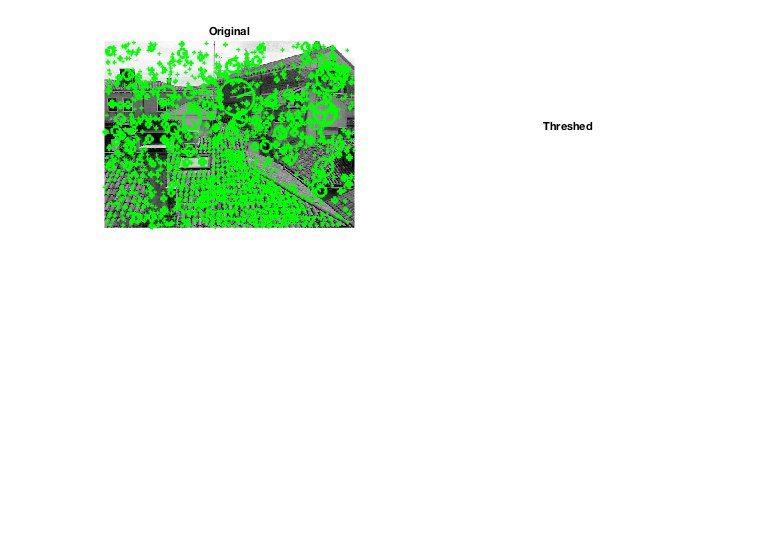

inc_thresh = 0.05;
dec_thresh = 0.002;
[f_threshed_more, ~] = vl_sift(I,'PeakThresh', inc_thresh);
[f_threshed_less, ~] = vl_sift(I,'PeakThresh', dec_thresh);
cla;

subplot(2,2,1), show_keypoints(I,f), title('Original'),...
subplot(2,2,2), show_keypoints(I,f_threshed), title(strcat('Thresh=', num2str(thresh))),...
subplot(2,2,3), show_keypoints(I,f_threshed_more), title(strcat('Thresh=', num2str(inc_thresh))),...
subplot(2,2,4), show_keypoints(I,f_threshed_less), title(strcat('Thresh=', num2str(dec_thresh)));

As the threshold is increased, less keypoints are detected, as expected. However, at a threshold value of 0.05, several keypoints are now missing such as the ones identified in problem 1. This means that although the threshold can be useful at small values to reduce noise, at larger values important keypoints are missed that can harm the analysis.

As the threshold is decreased, more keypoints are detected, as expected. However, there are still less keypoints detected than in the original image, which is equivalent to a peak threshold value of 0.

We now try to experiment with the edge threshold. The default value of the edge threshold is 10.

peak_thresh = 0.04;
[f_threshed, d_threshed] = vl_sift(I,'PeakThresh', peak_thresh);
edge_thresh = 10;
[f_threshed_edge, d_threshed_edge] = vl_sift(I,'PeakThresh', peak_thresh , 'EdgeThresh', edge_thresh);

**Question 4**: Try to slowly increase or decrease the threshold. Comment why the number of detected keypoints decreases when the threshold is decreased. Is this the expected behavior according to the way the threshold is defined?

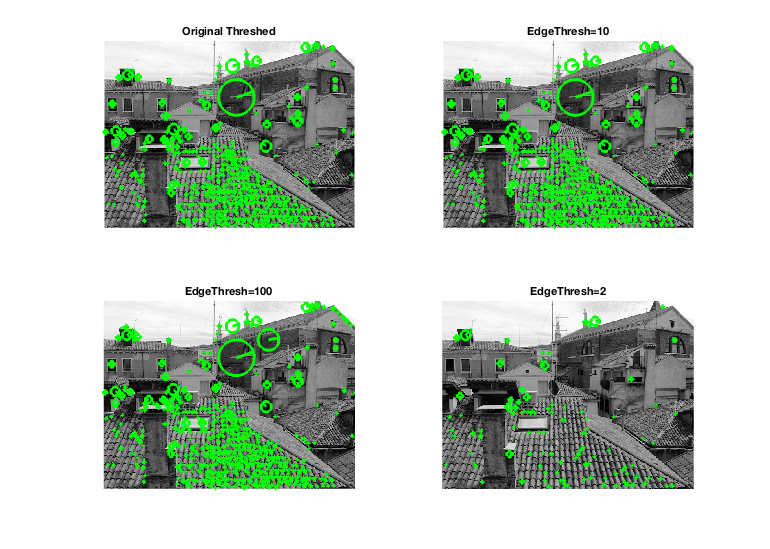

inc_edge_thresh = 100;
dec_edge_thresh = 2;
[f_threshed_more, d_threshed_more] = vl_sift(I,'PeakThresh', peak_thresh , 'EdgeThresh', inc_edge_thresh);
[f_threshed_less, d_threshed_less] = vl_sift(I,'PeakThresh', peak_thresh , 'EdgeThresh', dec_edge_thresh);
subplot(2,2,1); show_keypoints(I,f_threshed); title('Original Threshed');
subplot(2,2,2); show_keypoints(I,f_threshed_edge); title(strcat('EdgeThresh=', num2str(edge_thresh)));
subplot(2,2,3); show_keypoints(I,f_threshed_more); title(strcat('EdgeThresh=', num2str(inc_edge_thresh)));
subplot(2,2,4); show_keypoints(I,f_threshed_less); title(strcat('EdgeThresh=', num2str(dec_edge_thresh)));

When the edge threshold is increased, the resulting image detects a very similar number of keypoints, it does not make much of a difference. The number of keypoints does increase very slightly though (note the keypoints on the roof in the top right corner of the EdgeThresh=100 image). 

When the edge threshold is decreased, there is a notable decrease in the number of keypoints detected. For example, most of the small scale key points on the roof at the bottom of the image disappear. This is similar to increasing the peak threshold, however, whereas the peak threshold removes any peaks of D scale space below a value, the edge threshold removes them based on the curvature of the D scale space. 